% JK对比

clear; clc; close all;

%% 参数设定
D = 4000; 
s = 2000;

alpha1 = 6.4;         
beta = 0.61*alpha1;
gamma = 2.38*alpha1;


Ct = beta*gamma/(beta+gamma)*D/s;        % 全私家车通勤成本
n = 6;
Cb = 20;
Cab = Cb/n; % 平均公交成本

lambda = 4;        % 模块化公交效率参数
R_Nm_star = 500;      % 固定收益（R(N_m^*)）


%-------------------------------
% 专用道系数
%-------------------------------
theta = linspace(0.01, 0.99, 500)

theta =     0.0100    0.0120    0.0139    0.0159    0.0179    0.0198    0.0218    0.0237    0.0257    0.0277    0.0296    0.0316    0.0336    0.0355    0.0375    0.0395    0.0414    0.0434    0.0454    0.0473    0.0493    0.0512    0.0532    0.0552    0.0571    0.0591    0.0611    0.0630    0.0650    0.0670    0.0689    0.0709    0.0728    0.0748    0.0768    0.0787    0.0807    0.0827    0.0846    0.0866    0.0886    0.0905    0.0925    0.0944    0.0964    0.0984    0.1003    0.1023    0.1043    0.1062



% 专用
Nm_j = theta .* lambda ./(1-theta+theta .* lambda)*D/(2*n) .* (1-(1-theta) .* (Cab/Ct))

Nm_j =     6.0716    7.2389    8.3984    9.5500   10.6940   11.8305   12.9596   14.0814   15.1960   16.3037   17.4044   18.4983   19.5855   20.6661   21.7402   22.8080   23.8694   24.9247   25.9739   27.0171   28.0543   29.0858   30.1116   31.1317   32.1462   33.1553   34.1590   35.1574   36.1506   37.1386   38.1215   39.0994   40.0724   41.0406   42.0039   42.9626   43.9165   44.8659   45.8108   46.7512   47.6872   48.6189   49.5463   50.4695   51.3885   52.3034   53.2143   54.1212   55.0241   55.9232


p_j = 0.5 * ((1 ./ (1-theta)) .* Ct+Cab)

p_j =     4.8056    4.8118    4.8181    4.8244    4.8307    4.8370    4.8434    4.8498    4.8562    4.8626    4.8691    4.8756    4.8821    4.8887    4.8953    4.9019    4.9085    4.9151    4.9218    4.9285    4.9353    4.9420    4.9488    4.9557    4.9625    4.9694    4.9763    4.9832    4.9902    4.9972    5.0042    5.0113    5.0184    5.0255    5.0326    5.0398    5.0470    5.0542    5.0615    5.0688    5.0761    5.0835    5.0909    5.0983    5.1058    5.1133    5.1208    5.1283    5.1359    5.1436



C_j = 1/2 * Ct .* (1 ./ (1-theta+theta .* lambda) +...
    1 ./ (1-theta)) + 1/2 .* (theta .* lambda)./(1-theta+theta .* lambda) * Cab;
TTC_j = D*C_j

TTC_j = 1.0e+06 *

    0.0249    0.0249    0.0249    0.0249    0.0249    0.0249    0.0249    0.0249    0.0249    0.0249    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0250    0.0251    0.0251    0.0251    0.0251    0.0251    0.0251    0.0251    0.0251    0.0252    0.0252    0.0252    0.0252    0.0252    0.0252    0.0252    0.0253    0.0253    0.0253    0.0253    0.0253    0.0253    0.0254    0.0254    0.0254    0.0254    0.0254    0.0254    0.0255    0.0255


Pi_j = n .*Nm_j .*p_j + R_Nm_star - Nm_j .*Cb

Pi_j = 1.0e+05 *

    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061    0.0062    0.0063    0.0064    0.0065    0.0066    0.0067    0.0068    0.0069    0.0070    0.0071    0.0073    0.0074    0.0075    0.0076    0.0077    0.0078    0.0079    0.0080    0.0081    0.0083    0.0084    0.0085    0.0086    0.0087    0.0088    0.0089    0.0091    0.0092    0.0093    0.0094    0.0095    0.0096    0.0098    0.0099    0.0100    0.0101    0.0102    0.0103    0.0105    0.0106    0.0107    0.0108    0.0110    0.0111


CS_j = 1/2*1 ./(1-theta)*Ct*n .*Nm_j

CS_j = 1.0e+05 *

    0.0011    0.0014    0.0016    0.0018    0.0020    0.0023    0.0025    0.0027    0.0029    0.0031    0.0033    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0049    0.0051    0.0053    0.0055    0.0057    0.0059    0.0061    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0081    0.0083    0.0085    0.0087    0.0089    0.0091    0.0093    0.0095    0.0098    0.0100    0.0102    0.0104    0.0106    0.0108    0.0110    0.0112    0.0115    0.0117


SW_j = CS_j + Pi_j

SW_j = 1.0e+06 *

    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0017    0.0018    0.0018    0.0018    0.0019    0.0019    0.0019    0.0020    0.0020    0.0020    0.0021    0.0021    0.0021    0.0022    0.0022    0.0022    0.0023





% 间歇性专用
Nm_k = theta .* lambda ./ (1 - theta + theta .* lambda) * D / (2 * n) ...
     .* (1 -  (Cab / Ct))

Nm_k =     6.0022    7.1401    8.2652    9.3776   10.4776   11.5653   12.6410   13.7049   14.7572   15.7979   16.8275   17.8459   18.8535   19.8503   20.8365   21.8124   22.7780   23.7336   24.6793   25.6152   26.5415   27.4583   28.3658   29.2641   30.1534   31.0338   31.9055   32.7685   33.6230   34.4691   35.3069   36.1366   36.9583   37.7720   38.5780   39.3763   40.1670   40.9503   41.7262   42.4948   43.2563   44.0107   44.7581   45.4987   46.2326   46.9597   47.6803   48.3944   49.1020   49.8034



p_k = 0.5 * (Ct + Cab)

p_k = 4.7742


Pi_k = n .* Nm_k .* p_k + R_Nm_star - Nm_k .* Cb

Pi_k = 1.0e+03 *

    0.5519    0.5617    0.5715    0.5811    0.5906    0.6000    0.6093    0.6185    0.6276    0.6366    0.6455    0.6543    0.6630    0.6716    0.6801    0.6886    0.6969    0.7052    0.7134    0.7214    0.7295    0.7374    0.7452    0.7530    0.7607    0.7683    0.7758    0.7833    0.7907    0.7980    0.8052    0.8124    0.8195    0.8265    0.8335    0.8404    0.8473    0.8540    0.8607    0.8674    0.8740    0.8805    0.8869    0.8933    0.8997    0.9060    0.9122    0.9184    0.9245    0.9306


CS_k = 0.5 * (lambda-1) ./lambda .* Ct .* n .* Nm_k

CS_k = 1.0e+03 *

    0.0839    0.0998    0.1156    0.1311    0.1465    0.1617    0.1768    0.1916    0.2064    0.2209    0.2353    0.2496    0.2636    0.2776    0.2914    0.3050    0.3185    0.3319    0.3451    0.3582    0.3712    0.3840    0.3967    0.4092    0.4217    0.4340    0.4462    0.4582    0.4702    0.4820    0.4937    0.5053    0.5168    0.5282    0.5395    0.5506    0.5617    0.5726    0.5835    0.5942    0.6049    0.6154    0.6259    0.6362    0.6465    0.6567    0.6668    0.6767    0.6866    0.6964


SW_k = CS_k + Pi_k

SW_k = 1.0e+03 *

    0.6358    0.6616    0.6870    0.7122    0.7371    0.7617    0.7861    0.8101    0.8339    0.8575    0.8808    0.9038    0.9266    0.9492    0.9715    0.9936    1.0154    1.0371    1.0585    1.0796    1.1006    1.1214    1.1419    1.1622    1.1823    1.2023    1.2220    1.2415    1.2609    1.2800    1.2990    1.3177    1.3363    1.3547    1.3730    1.3910    1.4089    1.4267    1.4442    1.4616    1.4788    1.4959    1.5128    1.5296    1.5462    1.5627    1.5790    1.5951    1.6111    1.6270


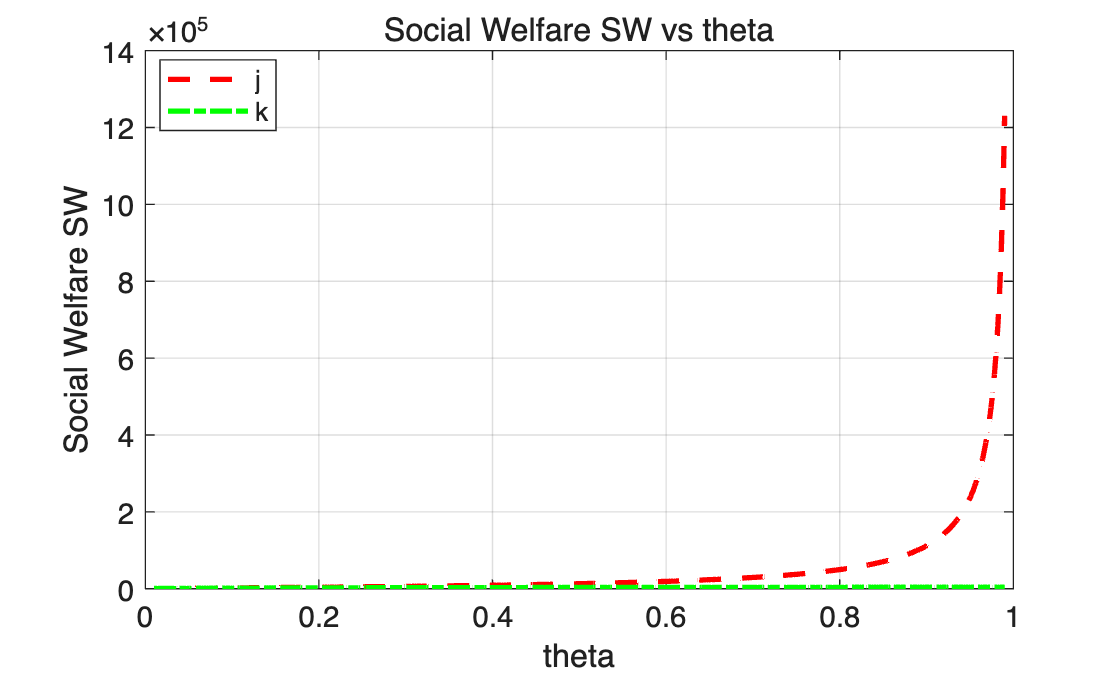


%% 绘图
figure;
plot(theta, SW_j, 'r--', 'LineWidth', 2); hold on;
plot(theta, SW_k, 'g-.', 'LineWidth', 2);
xlabel('theta'); ylabel('Social Welfare SW');
title('Social Welfare SW vs theta');
legend({'j','k'}, 'Location','best');
grid on; box on;


% 差值
delta_SW = SW_k - SW_j

delta_SW = 1.0e+06 *

   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006


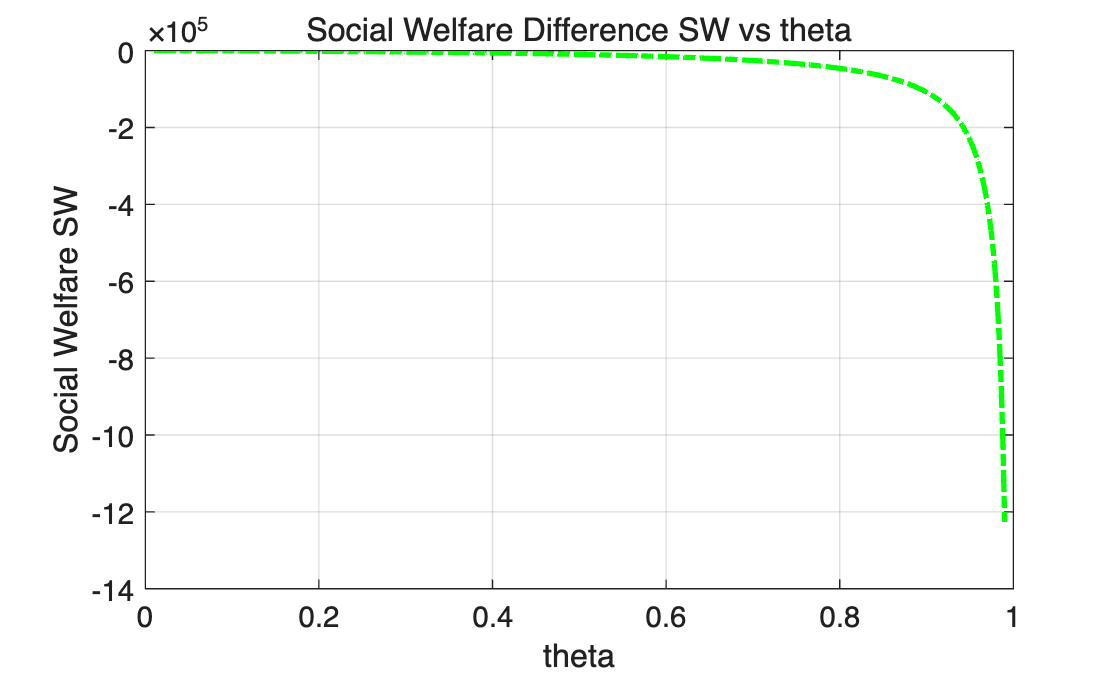


figure;
plot(theta, delta_SW, 'g-.', 'LineWidth', 2);
xlabel('theta'); ylabel('Social Welfare SW');
title('Social Welfare Difference SW vs theta');
grid on; box on;